%%%%%%%%%%%%%%%%%%%%%%
%%%import data
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder
ppbSDKPicarro = readtimetable("ppb SDK.xlsx", "Sheet", "Picarro", "VariableNamingRule", "preserve");

cd ../../../Raw/'From AirVision'/'Raw Exports'/

humid = readtimetable("Picarro_water_7-21_12-21.xlsx", "Sheet", "matlab");

cd ../../..

%%%%%%%%%%%%%%%%%%%%%%
%%%do comparison
%%%%%%%%%%%%%%%%%%%%%%

inds = isbetween(humid.Properties.RowTimes, ppbSDKPicarro.time(1), ...
    ppbSDKPicarro.time(end)); %make times match
compareSDKPicarro = synchronize(ppbSDKPicarro, humid(inds, :)); %create new table to synchronize
[mdl, stats] = makeLinMdl(compareSDKPicarro);

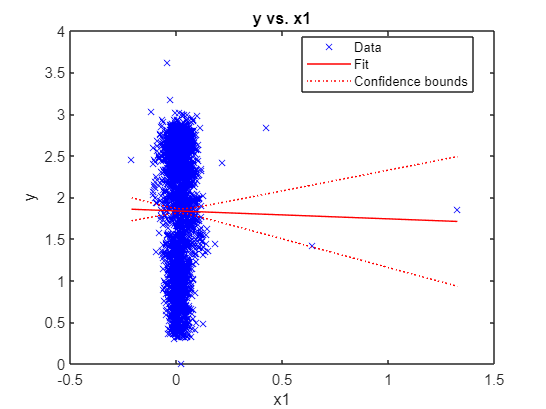

plot(mdl) %NO CORRELATION

function [mdl, stats] = makeLinMdl(data)
%%%makes a model of data from compiled comparison table for met and data

%%make model
temp = timetable2array(data);
mdl = fitlm(temp(:, 1), temp(:, 2));

%%populate stats
stats = table();
stats.n = sum(~isnan(table2array(mdl.Residuals(:, 1))));
stats.r = corr(temp(:, 1), temp(:, 2), "rows", "complete");
stats.intercept = table2array(mdl.Coefficients(1, 1));
stats.slope = table2array(mdl.Coefficients(2, 1));
end